# ARI - Homework 2		

% initialize
clear all
close all
clc

% useful commands
help eig

 eig    Eigenvalues and eigenvectors.
    E = eig(A) produces a column vector E containing the eigenvalues of 
    a square matrix A.
 
    [V,D] = eig(A) produces a diagonal matrix D of eigenvalues and 
    a full matrix V whose columns are the corresponding eigenvectors  
    so that A*V = V*D.
  
    [V,D,W] = eig(A) also produces a full matrix W whose columns are the
    corresponding left eigenvectors so that W'*A = D*W'.
 
    [...] = eig(A,'nobalance') performs the computation with balancing
    disabled, which sometimes gives more accurate results for certain
    problems with unusual scaling. If A is symmetric, eig(A,'nobalance')
    is ignored since A is already balanced.
 
    [...] = eig(A,'balance') is the same as eig(A).
 
    E = eig(A,B) produces a column vector E containing the generalized 
    eigenvalues of square ma

help ss

 ss  State-space models.
 
   Construction:
     SYS = ss(A,B,C,D) creates an object SYS representing the continuous- 
     time state-space model
          dx/dt = Ax(t) + Bu(t)
           y(t) = Cx(t) + Du(t)
     You can set D=0 to mean the zero matrix of appropriate size. SYS is 
     of type ss when A,B,C,D are dense numeric arrays, of type GENSS when 
     A,B,C,D depend on tunable parameters (see REALP and GENMAT), and 
     of type USS when A,B,C,D are uncertain matrices (requires Robust 
     Control Toolbox). Use SPARSS when A,B,C,D are sparse matrices.
 
     SYS = ss(A,B,C,D,Ts) creates a discrete-time state-space model with
     sample time Ts (set Ts=-1 if the sample time is undetermined).
 
     SYS = ss(D) specifies a static gain matrix D.
 
     You can set additional model properties by using name/value pairs.
     For example,
        sys = ss(-1,2,1,0,'InputDelay',0.7,'StateName','p

help tf

 tf  Construct transfer function or convert to transfer function.
 
   Construction:
     SYS = tf(NUM,DEN) creates a continuous-time transfer function SYS with
     numerator NUM and denominator DEN. SYS is an object of type tf when
     NUM,DEN are numeric arrays, of type GENSS when NUM,DEN depend on tunable
     parameters (see REALP and GENMAT), and of type USS when NUM,DEN are
     uncertain (requires Robust Control Toolbox).
 
     SYS = tf(NUM,DEN,TS) creates a discrete-time transfer function with
     sample time TS (set TS=-1 if the sample time is undetermined).
 
     S = tf('s') specifies the transfer function H(s) = s (Laplace variable).
     Z = tf('z',TS) specifies H(z) = z with sample time TS.
     You can then specify transfer functions directly as expressions in S
     or Z, for example,
        s = tf('s');  H = exp(-s)*(s+1)/(s^2+3*s+1)
 
     SYS = tf

help rank

 rank   Matrix rank.
    rank(A) provides an estimate of the number of linearly
    independent rows or columns of a matrix A.
 
    rank(A,TOL) is the number of singular values of A
    that are larger than TOL. By default, TOL = max(size(A)) * eps(norm(A)).
 
    Class support for input A:
       float: double, single

    Documentation for rank
    Other functions named rank



help ctrb

 ctrb  Compute the controllability matrix.
 
    CO = ctrb(A,B) returns the controllability matrix [B AB A^2B ...].
 
    CO = ctrb(SYS) returns the controllability matrix of the 
    state-space model SYS with realization (A,B,C,D).  This is
    equivalent to ctrb(sys.a,sys.b).
 
    For ND arrays of state-space models SYS, CO is an array with N+2
    dimensions where CO(:,:,j1,...,jN) contains the controllability 
    matrix of the state-space model SYS(:,:,j1,...,jN).  
 
    See also ctrbf, ss.

    Other functions named ctrb




% type 'help' followed by the command to learn about that specific function
% using the percent sign allows comments in MATLAB
% to compile/run your livescript hit "run" at the top of your screen

When investigating the far side of the Moon it would be very useful to position a communication satellite on the orbit around the translunar Lagrange point L2 of the system Earth-Moon-satellite. This orbit is called “Halo orbit” and is depicted below. The advantage is that the satellite would be in connection both with the Earth and the far side of the Moon. Consider that we control the position of the satellite such that it is always close to this orbit. 

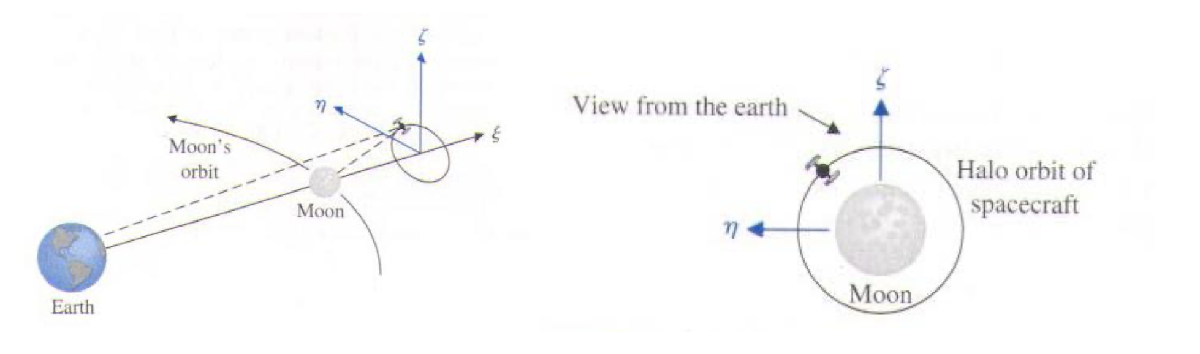The linearized and normalized model of the satellite’s movement around the translunar Lagrange point L2 is given as (Bishop-Dorf 2005, p. 720) 		


$$\dot{x} =\left\lbrack \begin{array}{cccccc}
0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & 0\\
0 & 0 & 0 & 0 & 0 & 1\\
7\ldotp 3809 & 0 & 0 & 0 & 2 & 0\\
0 & -2\ldotp 1904 & 0 & -2 & 0 & 0\\
0 & 0 & -3\ldotp 1704 & 0 & 0 & 0
\end{array}\right\rbrack x+\left\lbrack \begin{array}{c}
0\\
0\\
0\\
1\\
0\\
0
\end{array}\right\rbrack u_1 +\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
1\\
0
\end{array}\right\rbrack u_2 +\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0\\
1
\end{array}\right\rbrack u_{3,}$$
	 				

where the state vector consists of positions and velocities ($x=[\xi, \zeta, \eta, \dot{\xi}, \dot{\zeta}, \dot{\eta}]^T
$) and the inputs $u_1$, $u_2$, and $u_3$are accelerations caused by rocket propulsion. The directions of the states and inputs are 𝜉, 𝜁, 𝜂, as shown in the figure. 

## Tasks 	

*Please answer the following in the spaces provided below, justify your conclustion:										*

- Is this linear system stable? If it is, then also the translunar equilibrium is stable.	

% insert your code here
A = [0 0 0 1 0 0;0 0 0 0 1 0;0 0 0 0 0 1; 7.3809 0 0 0 2 0;0 2.1904 0 2 0 0;0 0 3.1904 0 0 0];
B1 = [0;0;0;1;0;0];
B2 = [0;0;0;0;1;0];
B3 = [0;0;0;0;0;1];
B = [B1,B2,B3];
roots = eig(A);
for point=roots
    disp(point)
    if point > 0
        disp("The system is not stable")
        break
    end
   
end

   -3.5002
    3.5002
   -1.1487
    1.1487
    1.7862
   -1.7862



- Determine the input, from which the system is controllable. **Hint:** Since we have so far discussed the systems with one input only, determine the controllability for each input separately. 	

% insert your code here							
sys1 = ss(A,B1, [0 0 0 0 0 0],[0]);
sys2 = ss(A,B2, [0 0 0 0 0 0],[0]);
sys3 = ss(A,B3, [0 0 0 0 0 0],[0]);
C1 = [B1, A*B1, A^2*B1, A^3*B1, A^4*B1, A^5*B1];
C2 = [B2, A*B2, A^2*B2, A^3*B2, A^4*B2, A^5*B2];
C3 = [B3, A*B3, A^2*B3, A^3*B3, A^4*B3, A^5*B3];
disp("The ranks for the controllability of all 3 inputs are as follows respectively:")

The ranks for the controllability of all 3 inputs are as follows respectively:


disp([rank(C1)==6, rank(C2)==6, rank(C3)==6])

   0   0   0



- For each input separately, calculate the transfer function to the state. Can you find out the same property as in the point 2? **Hint:** Use the state as the output in calculating the transfer function. 	

% insert your code here		
zpk(ss(A, B1, [1 1 1 1 1 1], [0]))

ans =
 
      (s+2.786) (s+1) (s-0.7862)
  -----------------------------------
  (s+3.5) (s-3.5) (s+1.149) (s-1.149)
 
Continuous-time zero/pole/gain model.



zpk(ss(A, B2, [1 1 1 1 1 1], [0]))

ans =
 
       (s-1.895) (s+1) (s+3.895)
  -----------------------------------
  (s+3.5) (s-3.5) (s+1.149) (s-1.149)
 
Continuous-time zero/pole/gain model.



zpk(ss(A, B3, [1 1 1 1 1 1], [0]))

ans =
 
         (s+1)
  -------------------
  (s-1.786) (s+1.786)
 
Continuous-time zero/pole/gain model.



- Consider now the full system, including all three inputs. Check its controllability. **Hint:** Formally do the same procedure as in task 2, that is, calculate the controllability matrix. Instead of having a column matrix B we have now a matrix of input vectors with dimension 6x3. Then calculate its rank and test, if this rank is equal to the system order. 		

% insert your code here
Con = [B, A*B, A^2*B, A^3*B, A^4*B, A^5*B];
disp("The rank for the controllability of inputs:")

The rank for the controllability of inputs:


disp(rank(Con))

     6



- Calculate the transfer function matrix considering all inputs to all states. 						

% insert your code here
zpk(ss(A,B, [1 1 1 1 1 1],[1 1 1]))

ans =
 
  From input 1 to output:
  (s+3.614) (s+1.17) (s-1.368) (s-2.417)
  --------------------------------------
   (s+3.5) (s-3.5) (s-1.149) (s+1.149)
 
  From input 2 to output:
  (s+3.414) (s+1.221) (s-2.911) (s-0.7242)
  ----------------------------------------
    (s+3.5) (s-3.5) (s-1.149) (s+1.149)
 
  From input 3 to output:
  (s-1.062) (s+2.062)
  -------------------
  (s-1.786) (s+1.786)
 
Continuous-time zero/pole/gain model.

